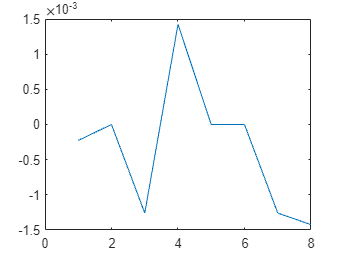

% creating a N x 1 array to store the integral sum Pij
% assuming the equation ran at the boundary is
% Fi x Iij = [mu*Pij - 2*pi*mu* U(xo)]

P_cell = cell(N_o_el,1);

for n = 1:N_o_el
    xo = x_bound(n); yo = y_bound(n);
    t_mat = zeros(2,1);
    for j = 1:2
        for m = 1:N_o_el
            x = x_bound(m); y = y_bound(m);

            for i = 1:2
                if (m >= 1) && (m <= 0.25*N_o_el) % Lower boundary
                    lim_1 = x + 2/N_o_el; %upper limit
                    lim_2 = x - 2/N_o_el; %lower limit
                    t_mat(j) = t_mat(j) +  mu.*U(m,i).*St_int(x,xo,y,yo,i,j,2,1,lim_1,lim_2);
                end
                if (m >= 1 + 0.25*N_o_el) && (m <= 0.5*N_o_el) % Right boundary
                    lim_1 = y + 2/N_o_el; %upper limit
                    lim_2 = y - 2/N_o_el; %lower limit
                    t_mat(j) = t_mat(j) - mu.*U(m,i).*St_int(x,xo,y,yo,i,j,1,2,lim_1,lim_2);
                end
                if (m >= 1 + 0.5*N_o_el) && (m <= 0.75*N_o_el) % Top boundary
                    lim_1 = x - 2/N_o_el; %upper limit
                    lim_2 = x + 2/N_o_el; %lower limit
                    t_mat(j) = t_mat(j) - mu.*U(m,i).*St_int(x,xo,y,yo,i,j,2,1,lim_1,lim_2);
                end
                if(m >= 1 + 0.75*N_o_el) && (m <= N_o_el) % Left boundary
                    lim_1 = y - 2/N_o_el; %upper limit
                    lim_2 = y + 2/N_o_el; %lower limit
                    t_mat(j) = t_mat(j) + mu*U(m,i).*St_int(x,xo,y,yo,i,j,1,2,lim_1,lim_2);
                end
            end
        end
    end
    for j = 1:2
        t_mat(j) = t_mat(j) - 2*pi*mu*U(n,j);
    end

    P_cell{n} = t_mat;
end
P_mat = cell2mat(P_cell);
plot (P_mat)